Read images

folder = "DB0"; %%locate folder
imagefiles = dir(fullfile(folder,'*.jpg')); %%store the images
nfiles = length(imagefiles); %%define number of images.
Im = cell(1,nfiles); %%Allocate space

%%for each image
for i = 1:nfiles
  filename=fullfile(folder,imagefiles(i).name); %%get filename of current image.
  %subplot(nfiles/2, nfiles/2, i); %%define location to plot the image in our subplot.
  Im{i}=im2double(imread(filename)); %%Read the imagefile, convert to double and store it.
  %imshow(Im{i}) %%Show the current image in a subplot.
end

Convert to YCbCr and create an eye map according to the *Face Detection in Color Images* paper.

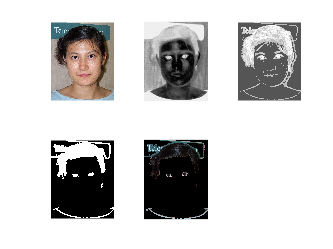

%The following requires image processing toolbox.
currentImage = Im{3};
[chromaIm, lumaIm, EyeMap] = eye_detection(currentImage);

%%Create a figure and subplot the eye maps. 
figure;
subplot(2,3,1);
imshow(currentImage);
subplot(2,3,2);
imshow(chromaIm)
subplot(2,3,3);
imshow(lumaIm);
subplot(2,3,4);
imshow(EyeMap);
subplot(2,3,5);
imshow(EyeMap.*currentImage);

Mouth map

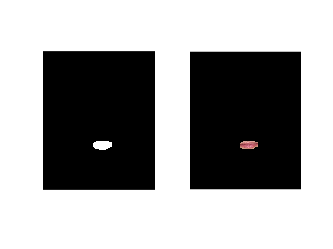

MouthMap = mouth_detection(currentImage);
figure;
subplot(1,2,1);
imshow(MouthMap);
subplot(1,2,2);
imshow(currentImage.*MouthMap);

Form an eye-mouth triangle.

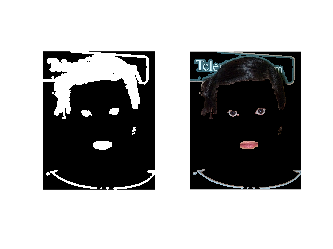

Triangle = EyeMap + MouthMap;
figure;
subplot(1,2,1);
imshow(Triangle);
subplot(1,2,2);
imshow(Triangle.*currentImage);